# land_PREprocess_main (script): 

# from .mff file to pre-processed data .set 

## 0) set path and trigger table - - - - - - - -  -- - - - - - -  -


% my laptop
path.project = 'C:\Users\andrea.vitale\Desktop\_PROJECT\CMI_EEG_HACKing_session'
path.eeglab = 'C:\Users\andrea.vitale\Desktop\_TOOLBOX\eeglab_20201226'
path.code = path.project;
%path.code = ''
path.data_mff = 'data_LAND_mff'
%path.data_set = 'data_LAND_set'
path.data_set = 'data_LAND_INSCAPE_set'
path.data_prep = 'data_LAND_prep'

cfg.path = path;

% add CODE folder to the path: 
addpath(genpath(cfg.path.code))

% open EEGLAB
cd(cfg.path.eeglab)
eeglab

% <<< TRIGGER TABLE <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<
% the list of the trigger table can be extended to include also other video/task
%(inscapes: begins and ends with 5 s during which a fixation cross is presented)

task = {'RS_cross';'RS_eyesclosed';'RS_inscapes'};
trigger_start = {'cros';'';'VidO'};
trigger_stop = {'';'';' '};
duration_sec = {''; ''; '420'}

cfg.trigger_table = table(task, trigger_start, trigger_stop, duration_sec)
% <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<


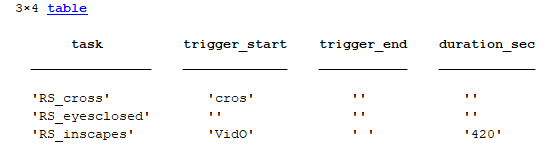

!!! work also in case the task_name is "Inscapes" (instead of "RS_inscapes")

## 1) split file_name in: subj_ID + session + task 


%subj_id = 'D9rj73y989'
%subj_id = 'D9tj73y989'
subj_id = 'a4mb6S3122'

%task_name = 'RS_inscapes'
task_name = 'Inscapes'
%task_name = 'RS_cross'
%task_name = 'RS_eyesclosed'

session_id = 'ses02'
%session_id = '02'
%session_numb = '03'
%session_numb = '04'  %????
%session_numb = '05'  %????


% DATA STRUCTURE temporary = = =  == =  = = = = = = = = = = = = = =
folder_name = [ subj_id '_' task_name '_' session_id ]
%folder_path = fullfile(project_dir, data_dir, folder_name)

% DATA STRUCTURE def = = =  == =  = = = = = = = = = = = = = = = = =
folder_name = [ subj_id '_' session_id '_' task_name ]

% = = =  == =  = = = = = = = = = = = = = = = = =  == =  = = = = = = 
cfg.folder_name = folder_name;
cfg.task_name = task_name;

cfg.do_save = 1;
cfg.do_save_eye = 1;
cfg.do_save_fig = 1;



## 2) search for the .mff file into the data folder and IMPORT


% IMPORT and CONVERT into .set format
[file_name, eeg_struct] = land_mff2set(cfg, folder_name)
eeg_orig = eeg_struct; 
%eeg_struct = eeg_orig

% if do_save && ~isempty(file_name)
%      eeg_struct = pop_saveset( eeg_struct, 'filename', [file_name '.set'], ...
%          'filepath', fullfile(cfg.path.project, cfg.path.data_set))
% end


## 3) remove bad portion from the data

!!! if no event is present, the 1st sample is considered as the trigger onset 

and the last sample is defined according to the video/task duration (as in the trigger table)

ex: see tn95d...

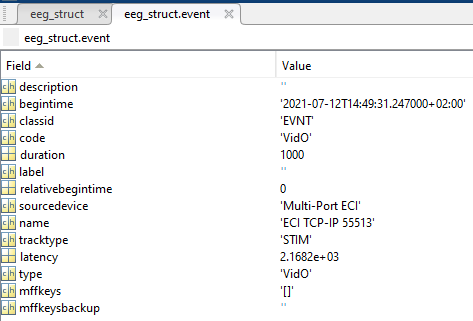

% !!! for now THIS WORKs only with eeg_struct ALREADY SEGMENTED 
% the VidO event corresponds to the onset of the video
% so we can remove the initial part of the recording %
% until the latency value (in sample ?) as reported in the trigger_table

[eeg_struct, event_start_msec, event_stop_msec] = land_segment_clean(cfg, eeg_orig)
eeg_nobadportion = eeg_struct;
cfg.event_orig_msec = [ event_start_msec, event_stop_msec ];
%cfg.event_sampleidx = [ event_start_sampleidx, event_stop_sampleidx ];

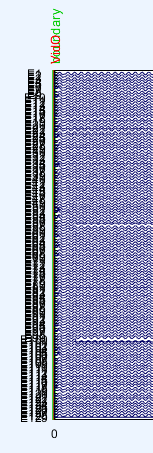

## 4) SAVE eeg_struct (without bad portion)  as .set file

if do_save && ~isempty(file_name)
     eeg_struct.cfg = cfg; %<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<
     eeg_struct = pop_saveset( eeg_struct, 'filename', [file_name '.set'], ...
         'filepath', fullfile(cfg.path.project, cfg.path.data_set))
end


## 5) run the PREPROCESSING pipeline

% <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<
% it can also start from the .set (segmented) data

% PREP parameters = = = = = = = =  ==  = = = ==  == = 
prep = [];
prep.downsample_rate = 500; % sampling rate to downsample to in Hz
                       % 500 instead of 250 in order to have a higher number of sample points
prep.hpf_cutoff = 1; % High pass filter in Hz
prep.lpf_cutoff = 80; % low pass filter cutoff in Hz

prep.line_noise_freq = 50; % line noise frequency in Hz
prep.line_noise_boundaries = 3; % how many Hz plus or minus the actual notch frequency to also include in the notch filter

% eye channels
prep.eye_channels = {'E128', 'E32', 'E25', 'E21', 'E127', 'E17', ...
    'E126', 'E14', 'E8', 'E1', 'E125'};
% see: JIA 2019, Measurement of saccadic eye movements by electrooculography for simultaneous EEG recording

% reject channels
%pp.do_chan_rejection = true;

% channels to reject
prep.chan_toreject = {
             'E127','E126',...
    'E25','E21','E17','E14','E8',...
    'E128','E32',          'E1','E125',...
    'E48','E43',            'E120','E119',...
    'E49',                          'E113',...
    'E56','E63',             'E99', 'E107',...
    'E68', 'E73', 'E81', 'E88', 'E94',...
               };

% interpolate channels
prep.do_chan_interp_pruning = true;

% channels to use for interpolation and then to PRUNE before ICA

!!! probably for this exploratory analysis  we have to increase the number of rejected channels 

ICA decomposition for 64 channels (n_chan^2 *20) requires = 81920 samples corresponding to ~160 sec

prep.chan_interp_prune =  {
    'E18','E10',...
    'E38','E121', ...
    'E44','E114', ...
    'E28','E117',...
    'E47','E98',...
    };

% parameters for IClabels classification and removal
prep.iclabels_params = [0 0.2;0.7 1;0.7 1;NaN NaN;0.7 1;0.7 1;0.7 1]; 
% probability threshold for ICA component being classified as brain
prep.brain_prob_thresh = prep.iclabels_params(1,2);


% ASR parameters - - - - - - - - - - - - - - -  -
prep.asr.iterations = 1; %5; <<<<<<<<<<<<<<<<<<<          % number of iterations to run ASR (reduced to 3)
prep.asr.chancrit = 0.8;                                  % 'ChannelCriterion'
prep.asr.lncrit = 4;                                      % 'LineNoiseCriterion'
prep.asr.flcrit = 5;                                      % 'FlatlineCriterion'
prep.asr.burstcrit = 20;                                  % 'BurstCriterion'
prep.asr.windowcrit = 'off';                              % 'WindowCriterion'
prep.asr.highpass = 'off';                                % 'Highpass'
prep.asr.burstrejection = 'off';                          % 'BurstRejection' -> NO rejection of bad samples
prep.asr.niter_bad_chan = round(prep.asr.iterations * 0.7); % n iterations for bad channels threshold


% FASTER parameters (variance and HURST) - - - - - - - - - - -


% pp.do_plot_chan = false;
% pp.do_plot_PSD = true;
% 
% pp.do_scorepoch = false;
% pp.do_save_score = true;
% 
% % file stem for final preprocessed and denoised dataset
% pp.final_pp_dn_fstem = 'preproc_icaDenoised';
% % file stem for final preprocessed but not denoised dataset
% pp.final_pp_nodn_fstem = 'preproc_notDenoised';
% 
% 
% % add pp to cfg
% cfg.pp = pp;
cfg.prep = prep;

eeg_prep = land_PREprocess_run(cfg, eeg_struct) %, run_on_server -> define this among the parameters
%eeg_prep = land_run_preproc(cfg, eeg_struct) %, run_on_server -> define this among the parameters


## (convert in function)

do_run_fun = 0
if do_run_fun
    clear all; close all
    cd('C:\Users\andrea.vitale\Desktop\_PROJECT\CMI_EEG_HACKing_session\data_LAND_mff')    
    list_mff_file = dir('*.mff')
    
    error_message = {}
    for i_subj = 1:length(list_mff_file)
    %for i_subj = 1:8
        %i_subj=14
        try 
            % convert this live script in a function:
            % EXAMPLE of usage
            file_name = list_mff_file(i_subj).name;
           
            %if ~contains(file_name, 'D9tj73y989') && ...
            %   ~contains(file_name, 'D9rj73y989') && ...
            %if   ~contains(file_name, 'Pilot003') && ...
            if contains(file_name, 'Zia2gu46hu') || ...
               contains(file_name, 'b4G72q9u65') || ...
               contains(file_name, 'jT12kn7195') || ...
               contains(file_name, 'Z9r8153s3a') || ...
               contains(file_name, 'Zr8153s3a') || ...
               contains(file_name, 'nscapes') %&& ...
               %i_subj ~= 14
            
                disp(['...processing ' file_name])  
               
                %file_name = 'a4mb6S3l22_01_Inscapes_20210726_010333.mff'
                %file_name = 'a4mb6S3l22_01_Inscapes_20210726_010333.set'
                
                % file_part = regexp(file_name,'_','split')
                % subj_id = file_part{1}
                % session_id = file_part{2}
                % task_name = file_part{3}
                % file_format = file_part{end}(end-2:end)
                
                [cfg, eeg_prep] = fun_LAND_main(file_name)
                %[cfg, eeg_prep] = fun_LAND_main(subj_id, task_name, session_id)
                %[cfg, eeg_prep] = fun_LAND_main(subj_id, task_name, session_id, file_format)
            end   
            
        catch error_message_tmp
            disp(error_message_tmp)
            error_message{i_subj+1} = error_message_tmp;
        end
    end
end